# Defines pattern time for pipe status via bin & normal functions.

## This example contains: 

- Load a network. 

- Get times. 

- Get Pipe infos. 

- Find the max length of link pipe names. 

- Create random status for pipes every hour. 

- Add all controls. 

- Unload library.

**Clear - Start Toolkit **

clear; close('all'); clc;
start_toolkit;

EPANET-MATLAB Toolkit Paths Loaded.


tic;

**Load network**

d=epanet('Net1.inp');

EPANET version {20200} loaded (EMT version {v2.2.1}).
Loading File "Net1.inp"...
Input File "Net1.inp" loaded successfully.


**Get times**

t = d.getBinTimesInfo;
hydstep = t.BinTimeHydraulicStep;
duration = t.BinTimeSimulationDuration;

**Get Pipe infos**

pipe_count = d.getLinkPipeCount;
pipeIDs = d.getLinkPipeNameID;

**Find the max length of link pipe names**

spsmax = max(cellfun('length',pipeIDs));

**Create random status for pipes every hour**

hrs = duration/3600;
hours = 0:hrs;
i=1; Time = cell(hrs,1);

for u=1:hrs
    % Create random status for pipes every hour.
    status_code = round(rand(1,pipe_count));
    status(find(status_code)) = {'Open  '};
    status(find(~status_code)) = {'Closed'};
    for np=1:pipe_count
        Time{i} = sprintf('%03d:%02d:00',hours(u), 30);
        sps = blanks(spsmax-length(pipeIDs{np}));
        Controls(i,: ) = ['LINK ',pipeIDs{np}, sps,' ', status{np}, ' AT CLOCKTIME ',Time{i}];
        i=i+1;
    end
end

**Add all controls**

d.addBinControl(Controls);

disp('Create random status')

Create random status


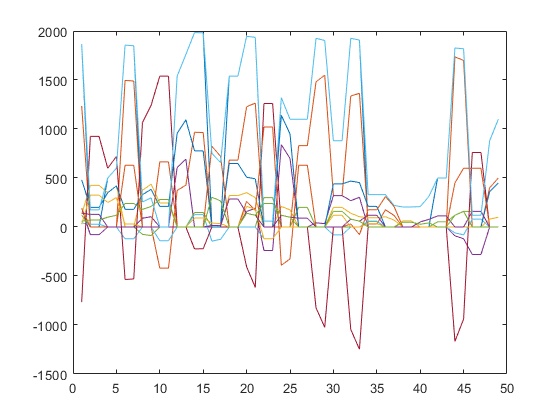

figure;
plot(d.getComputedHydraulicTimeSeries.Flow);

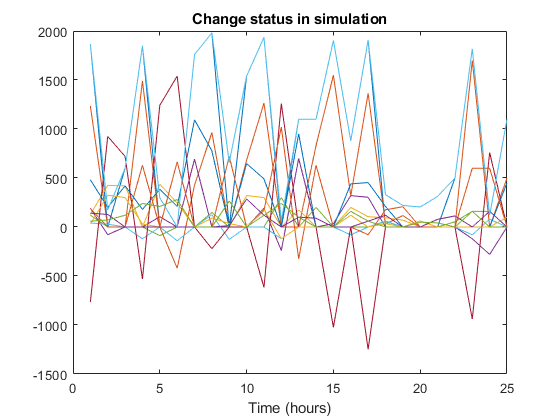


figure; %bin
plot(d.getComputedTimeSeries.Flow);
title('Change status in simulation');
xlabel('Time (hours)');

**Unload libraries**

d.BinClose;
d.unload;

EPANET Class is unloaded


toc

Elapsed time is 3.179216 seconds.
